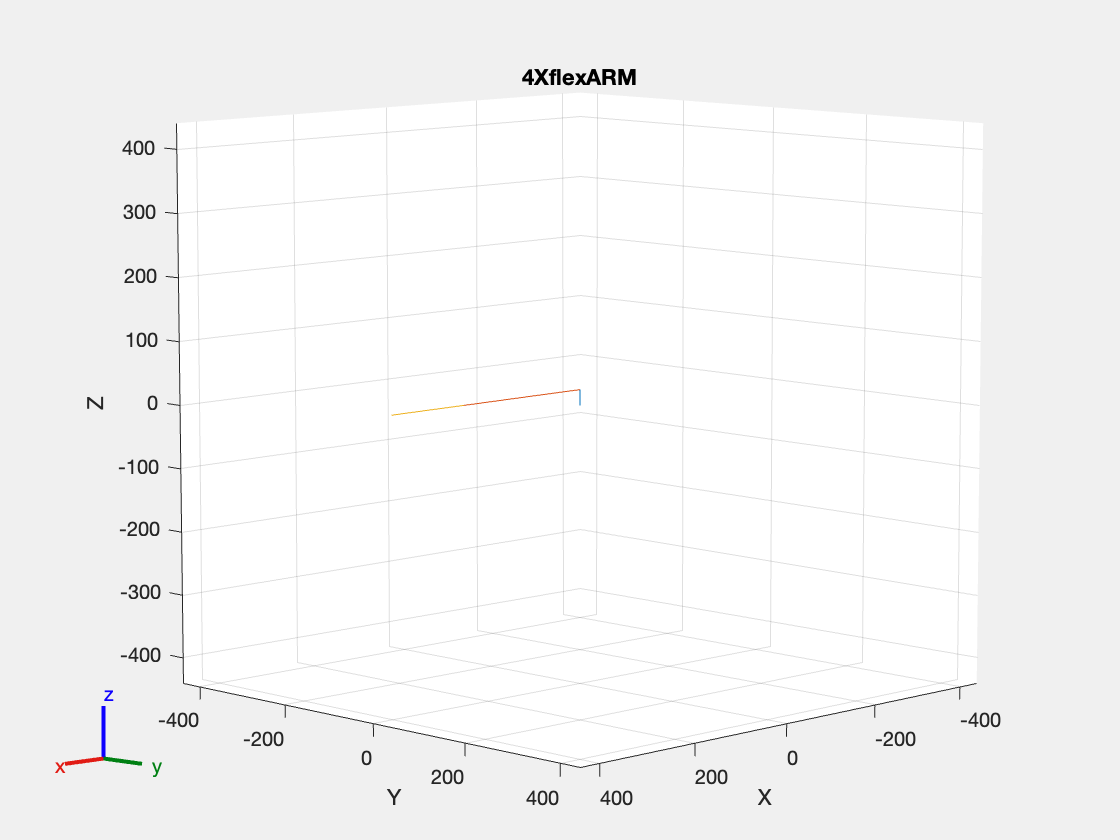

% Home position
theta1 = 0;
theta2 = 0;
theta3 = 0;
theta4 = pi/2;

% DH parameters of the manipulator
% [a, alpha, d, theta]
DHparameters = [
    0    -pi/2  25    theta1;
    250   0     0     theta2;
    150   pi/2  0     theta3 - pi/2;
    0     0     0     theta4
];

% Create a robot model
Robot = rigidBodyTree("DataFormat", "row", "MaxNumBodies", 4);

% Add each body and joint based on DH
% Base joint
Base = rigidBody('Base');
joint1 = rigidBodyJoint('joint1', 'revolute');
setFixedTransform(joint1, DHparameters(1,:), "dh");
Base.Joint = joint1;
addBody(Robot, Base, 'base');

% Shoulder joint
Shoulder = rigidBody('Shoulder');
joint2 = rigidBodyJoint('joint2', 'revolute');
setFixedTransform(joint2, DHparameters(2,:), "dh");
Shoulder.Joint = joint2;
addBody(Robot, Shoulder, 'Base');

% Elbow joint
Elbow = rigidBody('Elbow');
joint3 = rigidBodyJoint('joint3', 'revolute');
setFixedTransform(joint3, DHparameters(3,:), "dh");
Elbow.Joint = joint3;
addBody(Robot, Elbow, 'Shoulder');

% Wrist joint
Wrist = rigidBody('Wrist'); % Make sure 'Wrist' matches everywhere
joint4 = rigidBodyJoint('joint4', 'revolute');
setFixedTransform(joint4, DHparameters(4,:), 'dh');
Wrist.Joint = joint4;
addBody(Robot, Wrist, 'Elbow');

% Visualization of the robot
figure;
show(Robot);
title("4XflexARM");